Problem A 1.10:

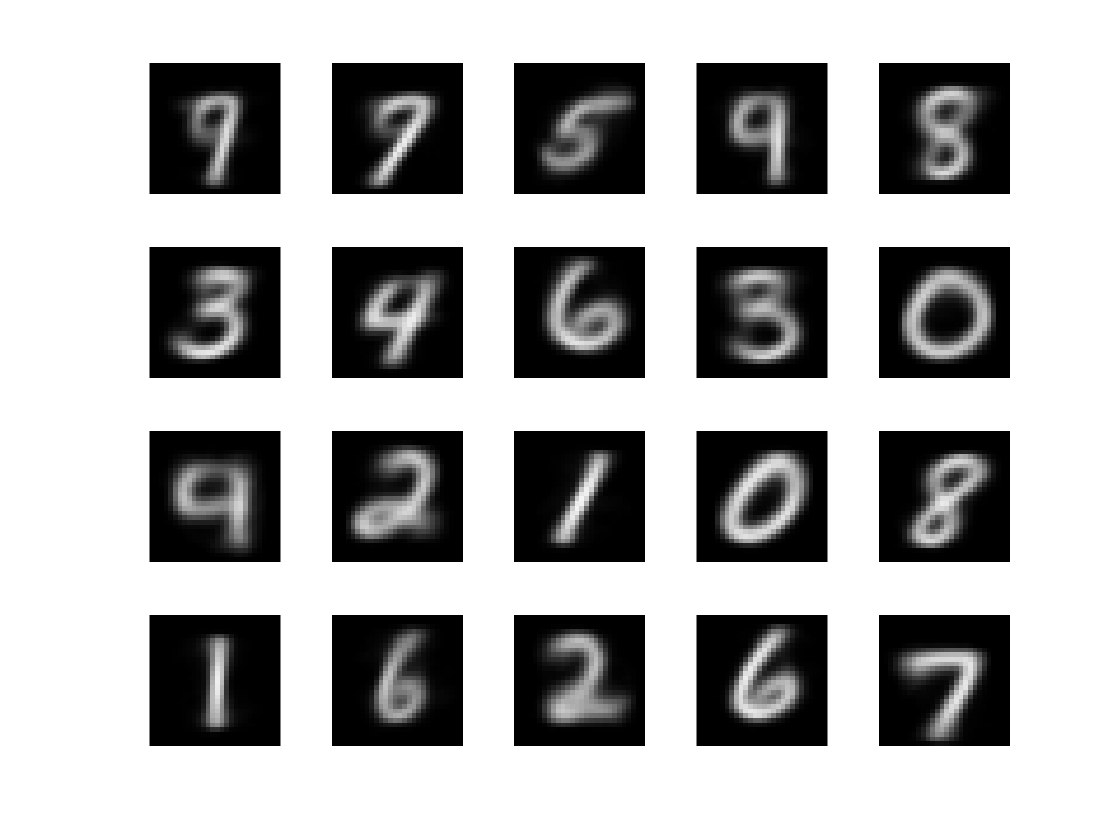

digits = digits(:, 1:10000);
group = randi(20, 1, 10000);
Z = zeros(784, 20);
Jprev = -1;

while 1
    % compute reps (Z)
    for i = 1:20
        I = find(group == i);
        Z(:, i) = mean(digits(:, I), 2)';
    end
    J = 0;
    for i = 1:size(digits, 2)
        mingroup = -1;
        minval = 100000;
        for j = 1:20
            tv = (norm(Z(:, j) - digits(:, i)))^2;
            if (tv < minval)
                minval = tv;
                mingroup = j;
            end
        end
        J = J + minval;
        group(i) = mingroup;
    end
    if (abs(J - Jprev) <= J / 100000)
        break;
    end
    Jprev = J;
end

for k=1:20
    subplot(4,5,k)
    imshow(reshape(Z(:,k), 28, 28));
end